# Problem 2

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
Re = 6378.1;
mu = 398600.4415;

Given:

r1_I = [3 1 0]'*Re

r1_I = 	1.0e+04 *

    1.9134
    0.6378
         0


r2_I = [-1 2*sqrt(3) 2]'*Re

r2_I = 	1.0e+04 *

   -0.6378
    2.2094
    1.2756


r1 = norm(r1_I)

r1 = 2.0169e+04

r2 = norm(r2_I)

r2 = 2.6298e+04

## Part a)

hhat = cross(r1_I,r2_I)/norm(cross(r1_I,r2_I))

hhat =     0.1535
   -0.4605
    0.8743


inc = acos(hhat(3)), inc_deg = rad2deg(inc)

inc = 0.5068

inc_deg = 29.0373

## Part b)

TA = acos(r1_I'*r2_I/r1/r2), TA_deg = rad2deg(TA)

TA = 1.5352

TA_deg = 87.9601

c = sqrt(r1^2 + r2^2 - 2*r1*r2*cos(TA))

c = 3.2567e+04

s = 1/2 * (r1+r2+c)

s = 3.9517e+04

amin = s/2

amin = 1.9758e+04

P1Fm = 2*amin - r1

P1Fm = 1.9348e+04

n = sqrt(mu/amin^3)

n = 2.2732e-04

alpha0 = 2*asin(sqrt(s/2/amin))

alpha0 = 3.1416

beta0 = 2*asin(sqrt((s-c)/2/amin))

beta0 = 0.8655

TOFmin = ((alpha0 - sin(alpha0)) - (beta0 - sin(beta0)))/n, TOFmin_hr = TOFmin/3600

TOFmin = 1.3362e+04

TOFmin_hr = 3.7117

## Part c)

TOF_hr = 3.6, TOF = TOF_hr*3600

TOF_hr = 3.6000

TOF = 12960

TOFpar = 1/3 * sqrt(2/mu)*(s^(3/2)-(s-c)^(3/2))

TOFpar = 5.4328e+03

[a,alpha,beta] = bisection(TOF,amin,c,mu,'1A',.001)

a = 1.9769e+04

alpha = 3.0946

beta = 0.8653

rho = asin(r2/c * sin(TA))

rho = 0.9390


p = 4*a*(s-r1)*(s-r2)/c^2 * sin((alpha+beta)/2)^2

p = 1.6052e+04

e = sqrt(1-p/a)

e = 0.4337


rD = r1

rD = 2.0169e+04

rA = r2

rA = 2.6298e+04

vD = sqrt(mu*(2/rD - 1/a))

vD = 4.4003

vA = sqrt(mu*(2/rA - 1/a))

vA = 3.1862

rp = a*(1-e)

rp = 1.1196e+04

ra = a*(1+e)

ra = 2.8343e+04

tsD = acos(1/e * (p/r1 - 1)), tsD_deg = rad2deg(tsD)

tsD = 2.0610

tsD_deg = 118.0855

tsA = tsD+TA, tsA_deg = rad2deg(tsA)

tsA = 3.5962

tsA_deg = 206.0456

h = sqrt(mu*p)

h = 7.9988e+04

gammaD = acos(h/r1/vD), gammaD_deg = rad2deg(gammaD)

gammaD = 0.4481

gammaD_deg = 25.6757

gammaA = -acos(h/r2/vA), gammaA_deg = rad2deg(gammaA)

gammaA = -0.3024

gammaA_deg = -17.3259

## Part d)

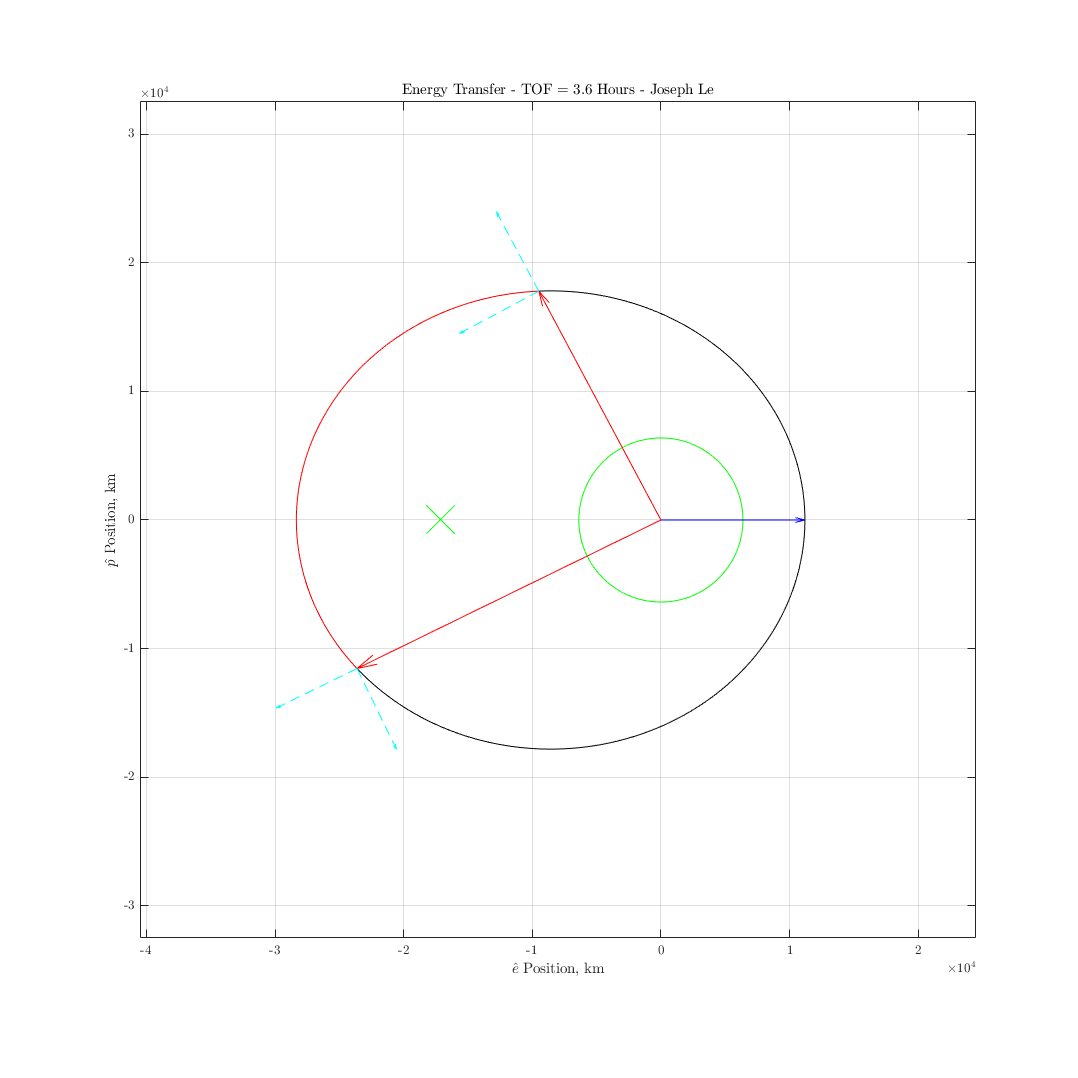

plotorbit(a,e,0,2*pi,0,'k')
hold on
plotorbit(a,e,tsA,tsD,0,'r')
plotorbit(Re,0,0,2*pi,0,'g')
plot(-2*a*e,0,'gX','markersize',30)
xlim(([-3.25 3.25]-.8)*1e4)
ylim(([-3.25 3.25])*1e4)
xlabel('$\hat{e}$ Position, km')
ylabel('$\hat{p}$ Position, km')
title('Energy Transfer - TOF = 3.6 Hours - Joseph Le')
set(gcf,'position',[0,0,1500,1500])
plotpos(a,e,tsD,'r',0,1)
plotpos(a,e,tsA,'r',0,1)
plotpos(a,e,0,'b',0,.000001)

th1 = 0; 
w = th1 - tsD, w_deg = rad2deg(w)

w = -2.0610

w_deg = -118.0855

## Part e)

ts1 = acos(3*Re/r1), ts1_deg = rad2deg(ts1)

ts1 = 0.3218

ts1_deg = 18.4349

iCr1 = [cos(ts1) -sin(ts1);sin(ts1) cos(ts1)]

iCr1 =     0.9487   -0.3162
    0.3162    0.9487


v1_R = [0 sqrt(mu/r1)]'

v1_R =          0
    4.4455


v1_I = [iCr1 * v1_R;0]

v1_I =    -1.4058
    4.2174
         0



iCrD = findDCM(ts1,inc,th1)

iCrD =     0.9487   -0.2765    0.1535
    0.3162    0.8294   -0.4605
         0    0.4854    0.8743


vD_I = iCrD * vD * [sin(gammaD); cos(gammaD); 0]

vD_I =     0.7123
    3.8923
    1.9249


dv_I = vD_I-v1_I

dv_I =     2.1181
   -0.3251
    1.9249


dvmag = norm(dv_I)

dvmag = 2.8805

Vhat = v1_I/norm(v1_I)

Vhat =    -0.3162
    0.9487
         0


Nhat = cross(r1_I,v1_I)/norm(cross(r1_I,v1_I))

Nhat =      0
     0
     1


Bhat = cross(Vhat,Nhat)

Bhat =     0.9487
    0.3162
         0


iCv1 = [Vhat,Bhat,Nhat];
vCi1 = iCv1';
dv_VBN = vCi1*dv_I

dv_VBN =    -0.9782
    1.9066
    1.9249


betaD = asin(dv_VBN(2)/dvmag)

betaD = 0.7233

alphaD = acos(dot(v1_I(1:2),dv_I(1:2))/norm(v1_I)/norm(dv_I(1:2))), alphaD_deg = rad2deg(alphaD)

alphaD = 2.0448

alphaD_deg = 117.1604

betaD = acos(dv_VBN(1)/dvmag/cos(alphaD)), betaD_deg = rad2deg(betaD)

betaD = 0.7319

betaD_deg = 41.9335

## Part f)

f = (1-r2/p * (1-cos(tsA-tsD)))

f = -0.5800

g = rA*rD/sqrt(mu*p)*sin(tsA-tsD)

g = 6.6268e+03

fdot = (dot([rA;0],vD*[sin(gammaD);cos(gammaD)])/p/rA * (1-cos(tsA-tsD)) - 1/rD*sqrt(mu/p)*sin(tsA-tsD))

fdot = -1.3236e-04

gdot = (1-rD/p*(1-cos(tsA-tsD)))

gdot = -0.2118


r2_I = f*r1_I+g*vD_I

r2_I = 	1.0e+04 *

   -0.6378
    2.2094
    1.2756


v2_I = fdot*r1_I+gdot*vD_I

v2_I =    -2.6835
   -1.6687
   -0.4077
